## Deliverable 1

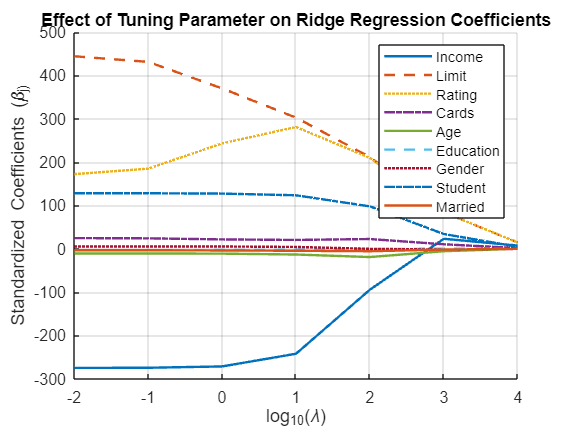

line_styles = {'-', '--', ':', '-.', '-', '--', ':', '-.', '-'};
colors = lines(9);
feature_names = df(1, 1:9).Properties.VariableNames;

% Create the plot
figure;
hold on;

% Plot each feature's coefficients as a function of the log-scaled tuning parameter
for j = 1:9
   plot(log10(lambda_values), coefficients_matrix(j, :), 'LineWidth', 1.5, ...
        'DisplayName', feature_names{j}, 'LineStyle', line_styles{j}, 'Color', colors(j, :));
end

xlabel('log_{10}(\lambda)');
ylabel('Standardized Coefficients (\beta_j)');
title('Effect of Tuning Parameter on Ridge Regression Coefficients');
legend('Location', 'northeast');
grid on;

hold off;

## Deliverable 2

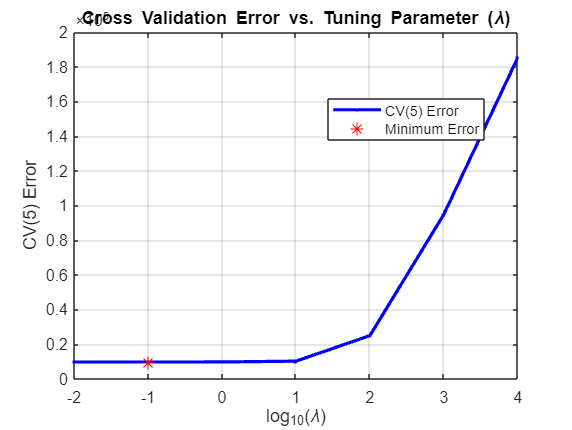

% Log-scaled lambda values
log_lambda_values = log10(lambda_values);

% Plot of CV(5) error vs. log-scaled lambda
figure;
plot(log_lambda_values, average_MSE, 'b.-', 'LineWidth', 2);
xlabel('log_{10}(\lambda)');
ylabel('CV(5) Error');
title('Cross Validation Error vs. Tuning Parameter (\lambda)');
grid on;

% Minimum CV(5) error pmarked w red circle
[~, min_error_idx] = min(average_MSE);
hold on;
plot(log_lambda_values(min_error_idx), average_MSE(min_error_idx), 'r*', 'MarkerSize', 8);

% Legend
legend('CV(5) Error', 'Minimum Error', 'Location', 'Best');

## Deliverable 3

fprintf('The value of 𝜆 that generated the smallest CV(5) error is %.4f\n', best_lambda);

The value of 𝜆 that generated the smallest CV(5) error is 0.1000


## Deliverable 4

fprintf('Estimated Model Parameters (beta hat):\n');

Estimated Model Parameters (beta hat):


for j = 1:length(beta_hat)
    fprintf('β_%d: %f\n', j, beta_hat(j));
end

β_1: -274.647089
β_2: 431.113092
β_3: 184.784975
β_4: 23.970323
β_5: -10.989822
β_6: -3.404717
β_7: 5.196441
β_8: 127.972373
β_9: -3.527596
